clc; clear all; close all;

## Defining DIR

path_images1 = "Data/Measurements1/";
path_images2 = "Data/Measurements2/";
path_bias = "Data/Bias";
path_dark = "Data/Dark"';
path_flat = "Data/Flat";

%Making one directory
cd('C:\Users\Admin\Desktop\LUT\SEM1\Digital Imaging\coin_detection\Durber\')
addpath functions
addpath Data/Measurements1/
addpath Data/Measurements2/


% Read all bias images
biasFiles = dir(fullfile(path_bias, '*.JPG'));
numBias = length(biasFiles);
biasImages = cell(1, numBias);  % Preallocate a cell array to store the images
for i = 1:numBias
    biasImages{i} = imread(fullfile(path_bias, biasFiles(i).name));
end

% Read all dark images
darkFiles = dir(fullfile(path_dark, '*.JPG'));
numDark = length(darkFiles);
darkImages = cell(1, numDark);  % Preallocate a cell array to store the images
for i = 1:numDark
    darkImages{i} = imread(fullfile(path_dark, darkFiles(i).name));
end

%Read all flat images 
flatFiles = dir(fullfile(path_flat, '*JPG'));
numFlat = length(flatFiles);
flatImages  = cell(1,numFlat);
for i = 1: numFlat
    flatImages{i} = imread(fullfile(path_flat, flatFiles(i).name));
end


% Initialize the mean and count variables
mean_B = 0;
mean_D = 0;
numBias = length(biasImages);
numDark = length(darkImages);

% Incrementally calculate the mean for bias images
for i = 1:numBias
    mean_B = mean_B + double(biasImages{i}); % Convert to double for accurate accumulation
end
mean_B = uint8(mean_B / numBias); % Final mean and conversion to uint8

% Incrementally calculate the mean for dark images
for i = 1:numDark
    mean_D = mean_D + double(darkImages{i}); % Convert to double for accurate accumulation
end
mean_D = uint8(mean_D / numDark); % Final mean and conversion to uint8

% Concatenate flat images along the third dimension and convert to double
flatStack = double(cat(3, flatImages{:}));

% Calculate normalized flat image (norm_F) and convert to uint8
norm_F = uint8(mean(flatStack, 3) / max(flatStack(:)));

## IMAGE CALIBRATION RESULT

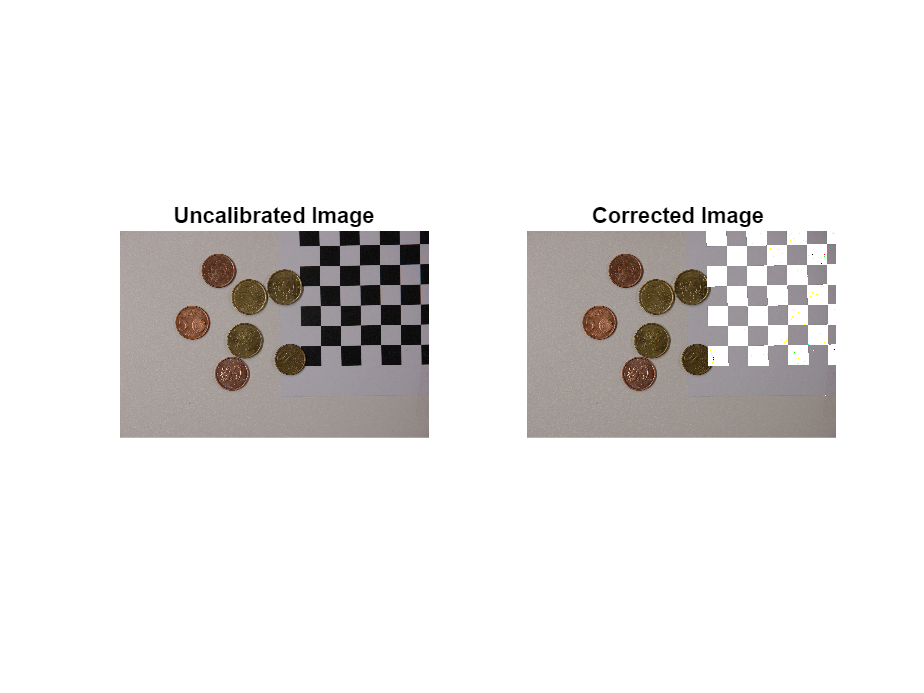

% Define the file path for the raw image
imageFilePath = path_images1 + '_DSC1775.JPG';

% Load the raw image from the file
InputImage = imread(imageFilePath);

% Apply the calibration formula to compute the corrected image
correctedImage = (InputImage - mean_B - mean_D) ./ norm_F;

% Create a figure to display the images
figure(1);

% Display the raw image
subplot(1, 2, 1);
imshow(uint8(InputImage));
title('Uncalibrated Image');

% Display the corrected image before checkerboard detection
subplot(1, 2, 2);
imshow(uint8(correctedImage));
title('Corrected Image ');


% Detect checkerboard points using MATLAB's built-in function
[detectedPoints, boardDimensions] = detectCheckerboardPoints(InputImage, 'PartialDetections', false);

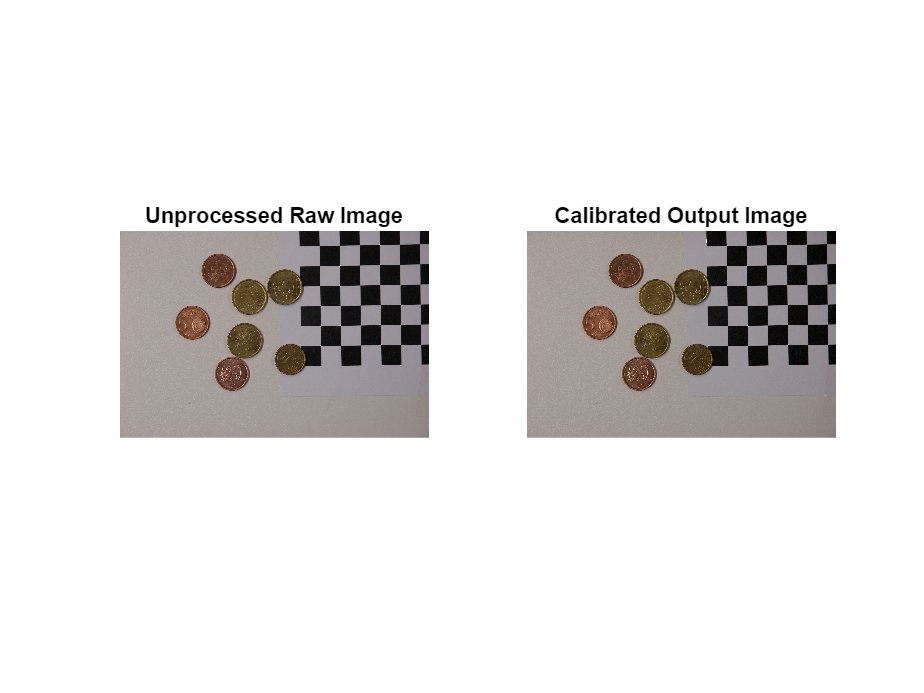


% Apply the calibration measurement function
calibratedOutput = calibration_measurement(InputImage, mean_B, mean_D, norm_F, detectedPoints, boardDimensions);

% Create a figure to visualize the images
figure(2);

% Display the original raw image
subplot(1, 2, 1);
imshow(uint8(InputImage));
title('Unprocessed Raw Image');

% Display the calibrated image
subplot(1, 2, 2);
imshow(calibratedOutput);
title('Calibrated Output Image');

# COIN ESTIMATION

% Detect and classify coins in a set of calibrated images.

% Define the list of image filenames to process
imageFiles = ["_DSC1772.JPG", "_DSC1773.JPG", "_DSC1774.JPG", "_DSC1775.JPG", ...
              "_DSC1776.JPG", "_DSC1777.JPG", "_DSC1778.JPG", "_DSC1779.JPG", ...
              "_DSC1780.JPG", "_DSC1781.JPG", "_DSC1782.JPG", "_DSC1783.JPG"];

% Get the number of images to process
numImages = length(imageFiles);

% Initialize an array to store the detected coins for each image
predicted = zeros(numImages, 6);

% Loop through each image in the list
for i = 1:numImages
    % Read the current image
    currentImage = imread(imageFiles(i));

    % Detect coins using the 'estim_coins' function
    detectedCoins = estim_coins(currentImage, mean_B, mean_D, norm_F);

    % Reverse the detected coins array
    reversedCoins = flip(detectedCoins);

    % Store the reversed coin counts in the 'predicted' array
    predicted(i, :) = reversedCoins;

    % Display the detected (reversed) coins for the current image
    fprintf('Image %s: Reversed Detected Coins: %s\n', imageFiles(i), mat2str(reversedCoins));
end

Image _DSC1772.JPG: Reversed Detected Coins: [1 0 2 1 1 1]


Image _DSC1773.JPG: Reversed Detected Coins: [3 1 0 1 0 0]


Image _DSC1774.JPG: Reversed Detected Coins: [1 0 0 5 1 1]


Image _DSC1775.JPG: Reversed Detected Coins: [0 0 0 3 1 3]


Image _DSC1776.JPG: Reversed Detected Coins: [0 1 0 4 1 3]


Image _DSC1777.JPG: Reversed Detected Coins: [0 1 1 2 0 2]


Image _DSC1778.JPG: Reversed Detected Coins: [0 0 1 3 0 0]
Image _DSC1779.JPG: Reversed Detected Coins: [0 0 4 0 0 3]


Image _DSC1780.JPG: Reversed Detected Coins: [0 0 0 0 1 3]


Image _DSC1781.JPG: Reversed Detected Coins: [0 0 1 4 0 0]


Image _DSC1782.JPG: Reversed Detected Coins: [0 3 1 5 0 0]


Image _DSC1783.JPG: Reversed Detected Coins: [0 3 1 1 0 0]



% Display the full predictions matrix
disp('Final Predicted Coin Counts (Reversed):');

Final Predicted Coin Counts (Reversed):


disp(predicted);

     1     0     2     1     1     1
     3     1     0     1     0     0
     1     0     0     5     1     1
     0     0     0     3     1     3
     0     1     0     4     1     3
     0     1     1     2     0     2
     0     0     1     3     0     0
     0     0     4     0     0     3
     0     0     0     0     1     3
     0     0     1     4     0     0
     0     3     1     5     0     0
     0     3     1     1     0     0



## EVALUATION 

% ground truth
measurement_dat = [
    1, 1, 1, 1, 1, 1;
    3, 1, 0, 1, 0, 0;
    1, 0, 0, 5, 1, 1;
    0, 0, 0, 3, 1, 3;
    0, 1, 0, 4, 1, 3;
    0, 3, 0, 1, 0, 2;
    0, 1, 0, 3, 0, 0;
    0, 0, 1, 4, 0, 3;
    0, 0, 0, 0, 1, 3;
    0, 0, 1, 4, 0, 0;
    0, 3, 1, 5, 0, 0;
    0, 3, 1, 1, 0, 0
];

% Compute element-wise absolute error for each measurement
euclidean = sqrt(sum((measurement_dat - predicted).^2, 2));

% Calculate the mean absolute error (MAE) for each row
mean_absolute_errors = mean(euclidean,2);

% Display the mean absolute errors for each image
disp('Mean Absolute Errors for Each Image:');

Mean Absolute Errors for Each Image:


disp(mean_absolute_errors);

    1.4142
         0
         0
         0
         0
    2.4495
    1.4142
    5.0000
         0
         0
         0
         0




% Compute overall MAE across all images
overall_mae = mean(mean_absolute_errors);
disp(['Overall Mean Absolute Error (MAE): ', num2str(overall_mae)]);

Overall Mean Absolute Error (MAE): 0.85649
